# **Laboratory work  4 - Approximations of Bode magnitude diagrams by asymptotes**

## **Bode diagram**

A **Bode diagram** is a graphical representation of a system's frequency response, how it behaves across a wide range of frequencies. It consists of two graphs plotted against frequency (ω) on a logaritmic scale:

    1. **Magnitude plot**: shows how much the system **amplifies or attenuates** signals at different frequencies, expressed in **decibels (dB)**

    2. **Phase plot**: shows the **phase shift (in degrees or radians)** as frequency changes

From previous laboratory works we can remember what is the cut-off frequency, what represents the corner frequencies and how we can convert to logaritmic scale.

In this laboratory, it is presented how we can approximate bode diagrams using straight-line asymptotes. To be able to start, we should know how the slope changes according to the type of singularity in the transfer function.

  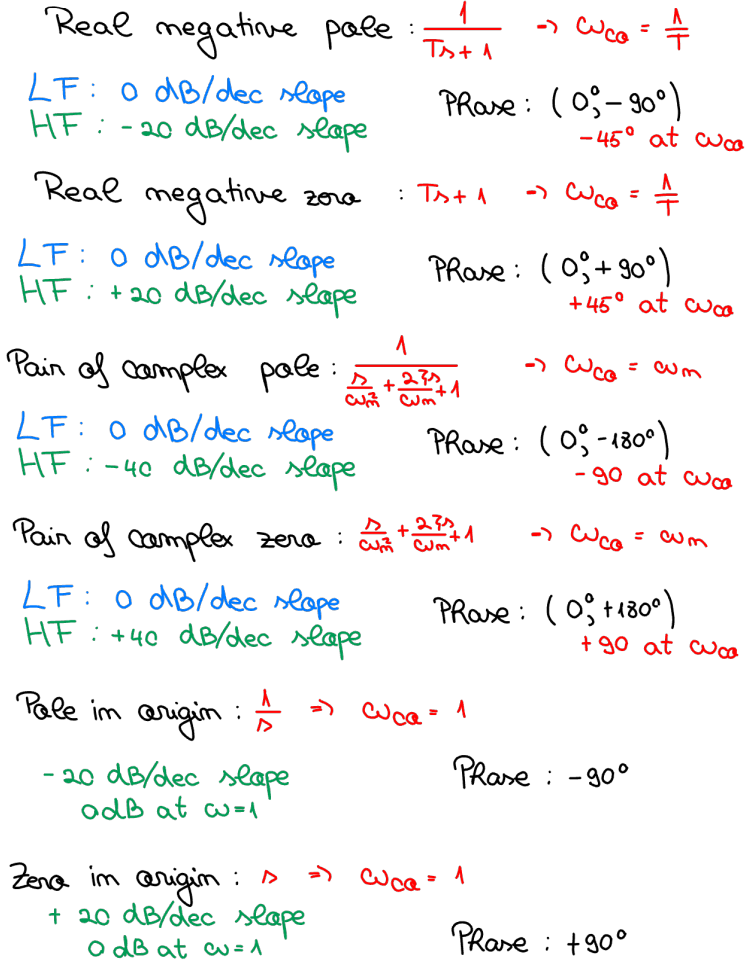                                        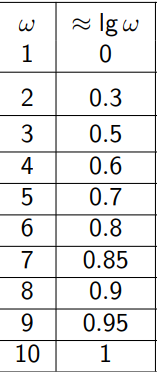

To compute such an approximation, we have to follow some steps. 

## **Problem**

Example: i) H(s) = 20$\frac{s+2}{\left(s+10\right)\left(s+5\right)}$

**Steps:**

            1. Transfer function - standard form: H(s) = k$\frac{\left(\textrm{T1s}+1\right)}{\left(\textrm{T2s}+1\right)}\ldotp \ldotp \ldotp$

                    H(s) = $20$$\frac{2\left(\frac{1}{2}s+1\right)}{10\left(\frac{1}{10}s+1\right)5\left(\frac{1}{5}s+1\right)}$ = $\frac{4}{5}$$\frac{\left(\frac{1}{2}s+1\right)}{\left(\frac{1}{10}s+1\right)\left(\frac{1}{5}s+1\right)}$

H = tf(20*[1 2], conv([1 10],[1 5]));
zpk(H)


ans =
 
    20 (s+2)
  ------------
  (s+10) (s+5)
 
Continuous-time zero/pole/gain model.


            2. Place the corner frequencies in the ascending order and mention the contribution to the slope: ω = $\frac{1}{\mathrm{T}}$

                    $\omega_2$ = 2 (+20dB), $\omega_3$ = 5 (-20dB), $\omega_4$ = 10 (-20dB)

            3. Range of the frequencies: $\pm 1\;\textrm{decade}\;\textrm{before}\;\textrm{and}\;\textrm{after}\;\textrm{smallest}/\textrm{biggest}$

                    Range = (${10}^{-1} ,{10}^2$)

w = [1e-1, 2, 5, 10, 1e2]; % vector that contains the frequencies in the ascending order + range margins

            4. Compute the approximation: for this step we will use semilogx function

                    - from ${10}^{-1}$ to $\omega_2$, the magnitude is ${\left|k|\right.}^{\mathrm{db}}$

k = 4/5; kdB = 20*log10(k); % converting the proportional gain in decibels

                    - from $\omega_2$ to $\omega_3$, a slope of +20dB occurs

kdiff23 = 20*log10(w(3)/w(2));

% kdiff is represented as the distance between two frequencies on a logarithmic scale converted in decibels/decade (slope)
% => change in magnitude over a specific frequency interval (kdiff = slope*lg(wi+1/wi))

                    - from $\omega_3$ to $\omega_4$, the slope induced is -20dB => the slope becomes 0dB

% kdiff34 = kdiff23; because the slope is 0dB => straight line

                    - from $\omega_4$ to ${10}^2$, the slope induced is -20dB => the slope becomes -20dB

kdiff45 = -20*log10(w(5)/w(4));

            5. Verify the accuracy using bodemag function

wl = logspace(-1, 2, 1e2); % we can specify on which decades the bode should be represented
bodemag(H, wl);
hold; grid; shg;

Current plot held


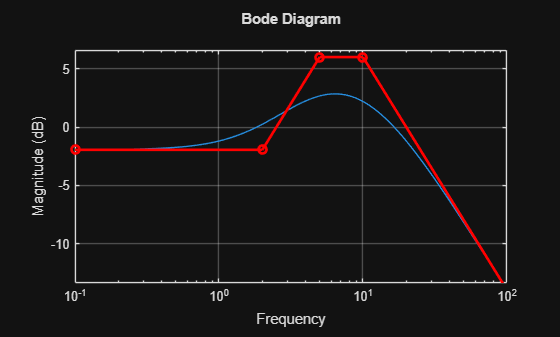

Current plot released


semilogx([w(1), w(2)], [kdB, kdB], '-o', 'LineWidth', 2, 'Color', 'r');
semilogx([w(2), w(3)], [kdB, kdB + kdiff23], '-o', 'LineWidth', 2, 'Color', 'r');
semilogx([w(3), w(4)], [kdB + kdiff23, kdB + kdiff23], '-o', 'LineWidth', 2, 'Color', 'r');
semilogx([w(4), w(5)], [kdB + kdiff23, kdB + kdiff23 + kdiff45], '-o', 'LineWidth', 2, 'Color', 'r');
hold;

In order to do this computation easier, I created the "bode_approx" function at the laboratory with the input parameters: H, k, w, s and wl; where ***H ***is the transfer funtion of the system***,*** ***k*** is the proportional gain of the transfer function, ***w*** is a vector containing the frequencies in the ascending order, ***s*** is a vector with the slopes after each corner frequency and ***wl ***which represents the range on which the bode is plotted. This function consists of a for loop and help us generalize the approximation process.

function [] = bode_approx(H, k, w, s, wl)

    kdB = 20*log10(k) + s(1)*log10(w(1)/1); 
    % a pole/zero in the origin gives +-20 slope line => we shift it to the starting frequency 
    bodemag(H, wl); grid; shg; hold;

    for i = 1:length(w)-1 
        % the loop repeats length(w)-1 times because in each current step we call the next value in the frequency vector
        kdbdiff = s(i)*log10(w(i+1)/w(i)); % computing the change in magnitude
        semilogx([w(i), w(i+1)], [kdB, kdB + kdbdiff], '-o', 'LineWidth', 2, 'Color', 'r');
        kdB = kdB + kdbdiff; % update the magnitude with the ending point of the previous asymptote
    end

    hold;

end

And now, let's apply this function on the same example.

Current plot held
Current plot released


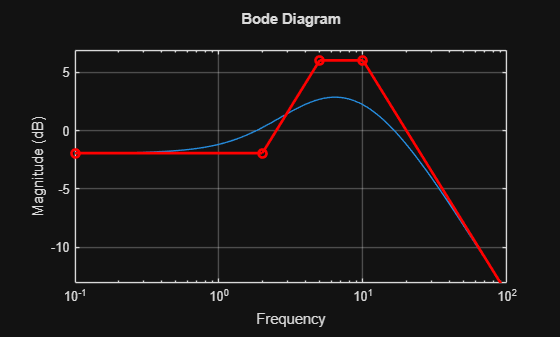

H = tf(20*[1 2], conv([1 10],[1 5]));
w = [1e-1, 2, 5, 10, 1e2]; % vector that contains the frequencies in the ascending order + range margins
s = [0, 20, 0, -20]; % vector with the slopes after each corner frequency
k = 4/5;
wl = logspace(-1, 2, 1e2); % margins for the bode plot
bode_approx(H, k, w, s, wl);

And now let's try with a transfer function that contains a zero in the origin.

H(s) = $\frac{15s}{\left(2s+3\right)\left(4s+1\right)}=\frac{15}{3}\frac{s}{\left(\frac{2}{3}s+1\right)\left(4s+1\right)}=5\frac{s}{\left(\frac{2}{3}s+1\right)\left(4s+1\right)}$ 

Current plot held
Current plot released


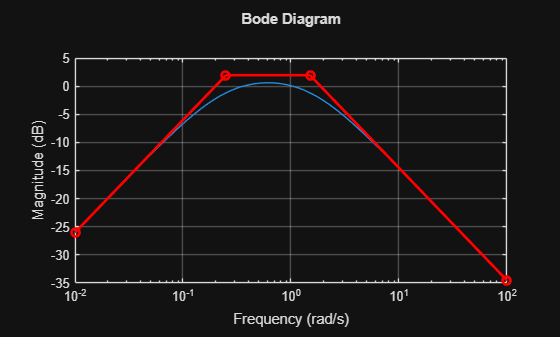

H = tf(15*[1 0], conv([2 3],[4 1]));
% w = 1/4, 3/2 (so the range is from 1e-1 to 1e1), k = 5; 
w = [1e-2, 1/4, 3/2, 1e2]; % vector that contains the frequencies in the ascending order + range margins
s = [20, 0, -20]; % vector with the slopes after each corner frequency
k = 5;
wl = logspace(-2, 2, 1e2); % margins for the bode plot
bode_approx(H, k, w, s, wl);